N = 1000

N = 1000

numbers = rand(1, N)

numbers =     0.4651    0.0509    0.0587    0.7415    0.6189    0.0643    0.5037    0.0003    0.5309    0.7245    0.7262    0.3126    0.0843    0.6881    0.8187    0.9058    0.4978    0.0495    0.6977    0.8286    0.4170    0.2435    0.9761    0.7587    0.9847    0.0726    0.2769    0.4983    0.6361    0.5373    0.6301    0.8257    0.4112    0.8213    0.3736    0.2063    0.4686    0.6657    0.0880    0.6792    0.9714    0.5023    0.6557    0.3896    0.8913    0.6426    0.6621    0.0845    0.8049    0.3688



num_bins = 16;
bin_edges = (0:num_bins) ./ num_bins

bin_edges =          0    0.0625    0.1250    0.1875    0.2500    0.3125    0.3750    0.4375    0.5000    0.5625    0.6250    0.6875    0.7500    0.8125    0.8750    0.9375    1.0000



function bin_loc = find_bin(bin_edges, number)
    for i = 1:(length(bin_edges)-1)
        % number fit within [bin_edge, bin_edge)
        if ( number >= bin_edges(i) ) && ( number < bin_edges(i+1) ) 
            bin_loc = i;
            break;
        end
    end
end

function counts = count_bins(bin_edges, data)
    counts = zeros(1, length(bin_edges) - 1);
    for i=1:length(data)
        bin_loc = find_bin(bin_edges, data(i));
        counts(bin_loc) = counts(bin_loc) + 1;
    end
end

counts = count_bins(bin_edges, numbers)

counts =     77    58    63    65    60    58    61    66    66    67    72    57    55    54    61    60


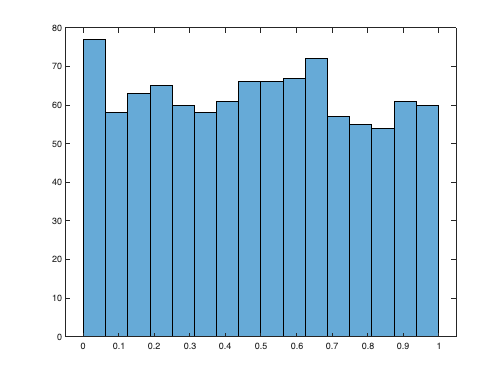

histogram(numbers, bin_edges)

Then I want to see how the observed compares to the actual

What is an actual? For each bin, there would be equal likely hood of finding.

function error = normalize_for_chi_sqaured(counts, N)
    num_bins = length(counts);
    uniform_per_bin_count = N / num_bins;
    true_uniform = zeros(1, num_bins) + uniform_per_bin_count; 
    error = sum( (counts - true_uniform).^2 ./ true_uniform );
end
normalize_for_chi_sqaured(counts, N)

ans = 9.0880

then we can plot what the best would have looked like

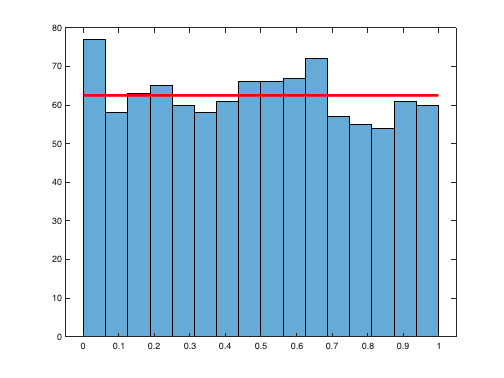

histogram(numbers, bin_edges)
hold on
plot([0 1], zeros(1, 2) + N / num_bins, "r-", "LineWidth", 3)
hold off

h_0 is that rand() is a uniform distrbution for n bins

b_1 unequal fruencies and not random uniform

alpha of 0.05 means that we reject h_0 5% of the time, when we should have failed to reject it.

num_bins = 16;
bin_edges = (0:num_bins) ./ num_bins;
endv = 12; startv = 4;
Ns = zeros(1, endv-startv+1);
outputs = zeros(1, endv-startv+1);
for i=startv:endv
    N_i = 2^i
    numbers_i = rand(1, N_i);
    counts_i = count_bins(bin_edges, numbers_i);
    outputs(i-startv+1) = normalize_for_chi_sqaured(counts_i, N_i);
    Ns(i-startv+1) = N_i;
end

N_i = 16

N_i = 32

N_i = 64

N_i = 128

N_i = 256

N_i = 512

N_i = 1024

N_i = 2048

N_i = 4096

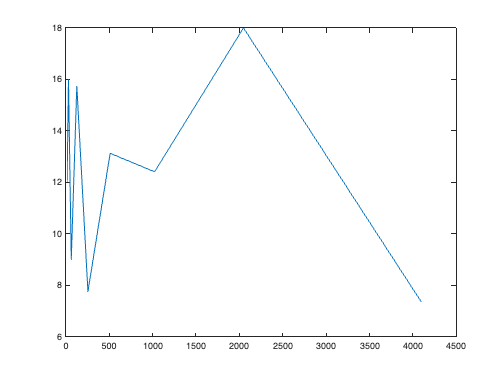

plot(Ns, outputs)

asdasdas

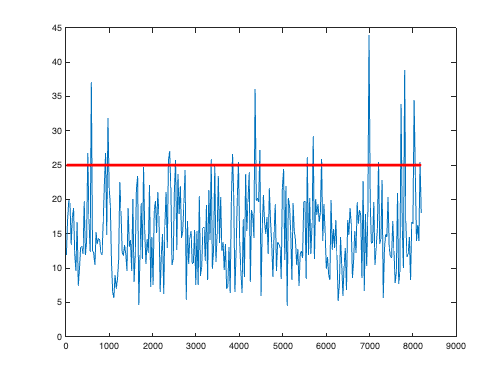

CRV = 24.996;
num_bins = 16;
bin_edges = (0:num_bins) ./ num_bins;
Ns = ceil(linspace(16, 2^13, 300));
outputs = zeros(1, length(Ns));
for i=1:length(Ns)
    N_i = Ns(i);
    numbers_i = rand(1, N_i);
    counts_i = count_bins(bin_edges, numbers_i);
    outputs(i) = normalize_for_chi_sqaured(counts_i, N_i);
end
plot(Ns, outputs)
hold on
plot([Ns(1) Ns(end)], zeros(1, 2) + CRV, "r-", "LineWidth", 3)
hold off